# **The heat equation**

## 1. Introduction

- Let's assume a 1-dimensional rod with length $L>0$ made of an isotropic material,

- The function $T(x,t)$ describes the heat of a point $x$ at time $t$, $x \in [ 0,L ]$, $t \in [0,\infty)$,

- At $t=0$, the rod has some initial heat distribution $T(x,0) = \phi(x)$,

- We assume no heat exchange with the enviornment.

Knowing that, is there a way to know how the heat distribution in the object changes over time? 

## 2. Joseph Fourier's study of heat flow

        *The Analytical Theory of Heat *(fr. *Théorie analytique de la chaleur*) is Fourier's 1822 publication of his work on heat flow. His work was based on Isaac Newton's law of cooling, which states:

*The rate of heat **loss of a body is directly proportional to the difference in the** temperatures **between the body and its environment.*

It is in this book where he famously stated, that any function can be expressed as an infinite sum of sine waves, which led to the invention of the fourier series and later, the fourier transform.


$$\frac{\partial T}{\partial t} = \alpha \cdot \frac{\partial^2 T}{\partial x^2$$


The heat equation for 1 dimension


$$\frac{\partial T}{\partial t} = \alpha \cdot \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2}+\frac{\partial^2 T}{\partial z^2} \right)$$


## 3. Heat flow in a 1-dimensional rod

Let's first look at a simplified example with a 1-dimensional rod insulated at both ends (No heat lost to the enviornment) and with an initial heat distribution $\phi (x)$

clc;clear;close all
opengl software
rod_length = 10;
runtime = 20;
first_peak_middle =2.2;
second_peak_middle = 6.9;
first_peak_value = 10;
second_peak_value = 20;
phi = @(x) first_peak_value*exp(-(x-first_peak_middle).^2)+second_peak_value*exp(-(x-second_peak_middle).^2);
position = linspace(0,rod_length,rod_length*20);
time = linspace(0,runtime,runtime*20);
sol = pdepe(0,@heatpde,phi,@heatbc,position,time);

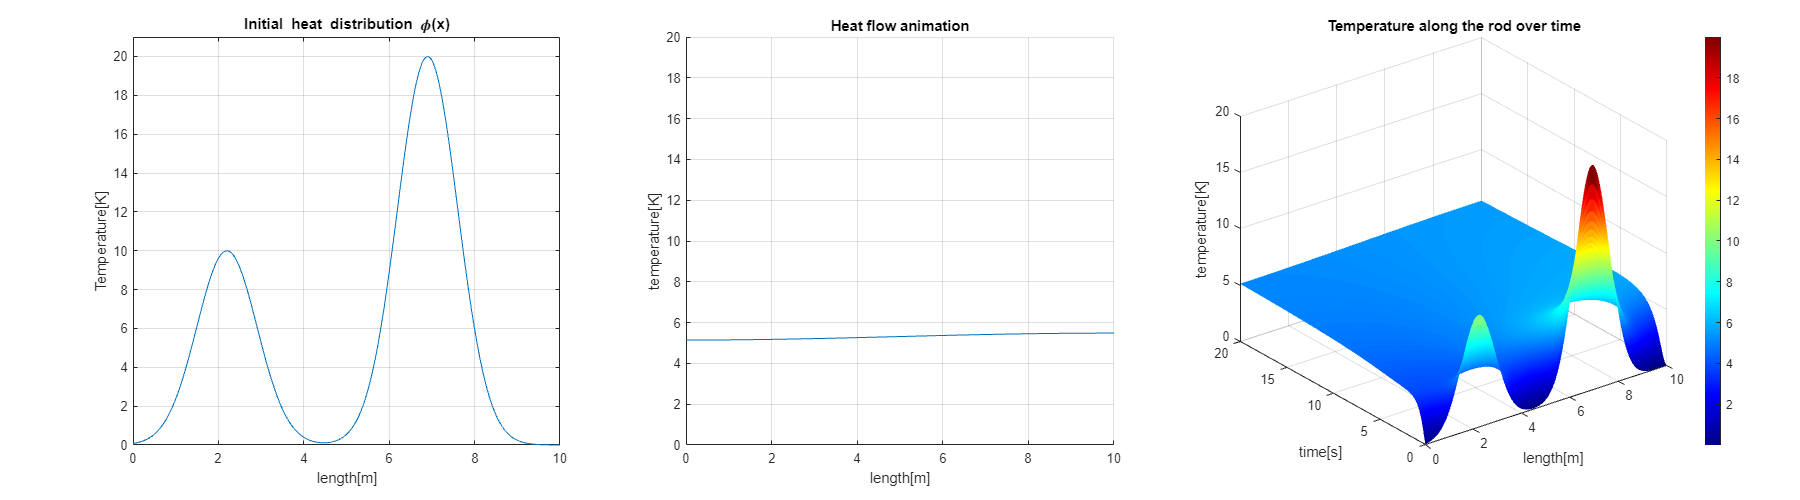

figure('name','Heat_flow_simulation','Position',[400 500 1800 500])
tiledlayout(1,3)
nexttile
    plot(position, phi(position));
    xlim([0 rod_length])
    ylim([0 max(phi(first_peak_middle),phi(second_peak_middle))+1])
    grid on
    title("Initial heat distribution \phi(x)")
    xlabel("length[m]")
    ylabel("Temperature[K]")
    colormap('jet')
nexttile
    hold on
    p_1 = plot(position,sol(1,:));
    grid on
    axis manual
    title("Heat flow animation")
    xlabel("length[m]")
    ylabel("temperature[K]")
nexttile
    temp = NaN(length(time),length(position));
    temp(1,:) = sol(1,:);
    p_2 = surf(position,time,temp,'EdgeColor','none');
    grid on
    axis ([0 rod_length 0 runtime 0 20])
    title("Temperature along the rod over time")
    xlabel("length[m]")
    ylabel("time[s]")
    zlabel("temperature[K]")
    colormap("jet")
    colorbar
    for k = 2:length(time)
        temp(k,:) = sol(k,:);
        set(p_1,'XData',position,'YData',sol(k,:))
        set(p_2,'XData',position,'YData',time,'ZData',temp)
        pause(0.01)
    end